num = 1

num = 1

denum = [1 6 10]

denum =      1     6    10



[A B C D] = tf2ss(num, denum)

A =     -6   -10
     1     0


B =      1
     0


C =      0     1


D = 0

A1 = [0 1; -10 -6]

A1 =      0     1
   -10    -6


B1 = [0 1]'

B1 =      0
     1


C1 = [1 0]

C1 =      1     0


D1 = 0

D1 = 0


sys1 = ss(A, B, C, D)

sys1 =
 
  A = 
        x1   x2
   x1   -6  -10
   x2    1    0
 
  B = 
       u1
   x1   1
   x2   0
 
  C = 
       x1  x2
   y1   0   1
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



sys2 = ss(A1, B1, C1, D1)

sys2 =
 
  A = 
        x1   x2
   x1    0    1
   x2  -10   -6
 
  B = 
       u1
   x1   0
   x2   1
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



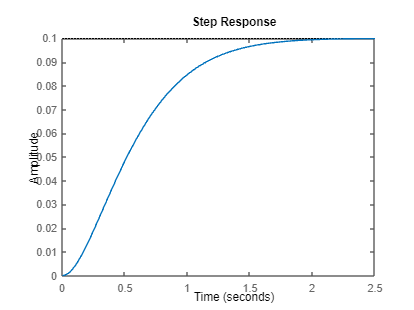


% Plot the step response of sys1
figure; % Creates a new figure window
step(sys1);


% Plot the step response of sys2 in a new figure
figure; % Creates another new figure window
step(sys2);

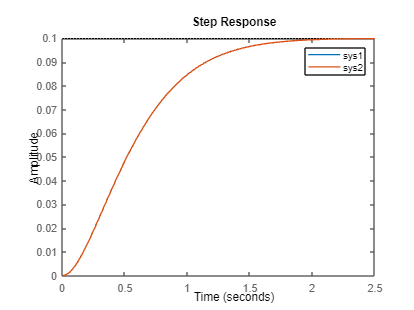


figure; % Creates a new figure window
step(sys1, sys2);
legend('sys1', 'sys2'); 